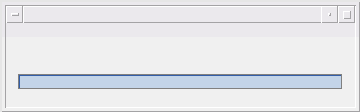

folders = dir("/home/lucas/githubRepos/MCSH_C_Implementation/processed/descriptors/GMPOrderNorm/64a9acbbcc41f61d4cf501fbe23eadd1/*.h5");
energy_files = dir("/home/lucas/githubRepos/MCSH_C_Implementation/energies/*.txt");
nstr = length(folders);
Data = cell(nstr,1);
nfps = 15;
for j = 1:nstr
    info = h5info(append(folders(j).folder,'/',folders(j).name));
    ngrps = length(info.Groups.Groups);
    Data{j}.x = [];
    for i = 1:ngrps
        name_metal = info.Groups(1).Groups(i).Name;
        test_h5 = transpose(h5read(append(folders(j).folder,'/',folders(j).name),append(name_metal,'/fps')));
        rows = size(test_h5,1);
        Data{j}.x(end+1:end+rows,:) = test_h5;
    end
    Data{j}.natom = size(Data{j}.x,1);
    fileID = fopen(append(energy_files(j).folder,'/',energy_files(j).name));
    test_ = fscanf(fileID,"%f");
    Data{j}.E = test_;
    waitbar(j/nstr)
end

copy = Data;
sums = zeros(1,15);
sum_sq = zeros(1,15);
denom = 0;

sums_E = 0;
sum_sq_E = 0;

for i=1:nstr
    x = copy{i}.x;
    E = copy{i}.E;
    sums = sums + sum(x,1);
    sums_E = sums_E + E;
    denom = denom + copy{i}.natom;
end
means = sums/denom;
means_E = sums_E/denom;
for i=1:nstr
    x = copy{i}.x;
    E = copy{i}.E;
    sum_sq = sum_sq + sum((x-means).^2,1);
    sum_sq_E = sum_sq_E + (E-means_E)^2;
end
stds = (sum_sq/denom).^(1/2);
stds_E = (sum_sq_E/denom)^(1/2);
count = 1;
for i = stds
    if i < 1e-6
        stds(count) = 1;
    end
    count = count + 1;
end

for i=1:nstr
    arr = copy{i}.x;
    Es = copy{i}.E;
    copy{i}.x = (arr-means)./stds;
    copy{i}.E = (Es-means_E)/stds_E;
end

Data = copy;
save data.m Data